# 2.1. Общие сведения

Для тока

clear
syms I_m omega t psi_i i(t)
i(t)==I_m*sin(omega*t+psi_i)

$$ans = i\left(t\right)=I_{m}\,\sin\left(\psi_{i}+\omega \,t\right)$$

комплексные мгновенного значение имеет вид

syms id
id==I_m*exp(1j*(omega*t+psi_i))==I_m*exp(1j*psi_i)*exp(1j*omega*t)== ...
I_m*cos(omega*t+psi_i)+1j*I_m*sin(omega*t+psi_i)

$$ans = \left(\left(\text{id}=I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}+\omega \,t\,\mathrm{i}}\right)=I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\right)=I_{m}\,\cos\left(\psi_{i}+\omega \,t\right)+I_{m}\,\sin\left(\psi_{i}+\omega \,t\right)\,\mathrm{i}$$

Мнимая часть комплексного мгновенного значения равна i(t):

i(t)==imag(I_m*exp(1j*(omega*t+psi_i)))

$$ans = i\left(t\right)=\mathrm{imag}\left(I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}+\omega \,t\,\mathrm{i}}\right)$$

Комплексное число 

syms Id_m Id I
Id_m==I_m*exp(1j*psi_i)

$$ans = {\mathrm{Id}}_{m}=I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}$$

называют комплексным амплитудным значением или комплексной амплитудой, а

Id==Id_m/sqrt(2)==I*exp(1j*psi_i)

$$ans = \left(\mathrm{Id}=\frac{\sqrt{2}\,{\mathrm{Id}}_{m}}{2}\right)=\text{I}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}$$

-комплексным действующим значением тока.

Аналогично определяются комплексные мгновенные значения синусоидальных напряжений, э. д. с., электрических зарядов, магнитных потоков и т. д.

syms t u(t) U_m e(t) E_m psi_u psi_e Ud_m Ed_m U E

Так, напряжению и ЭДС 

u(t)==U_m*sin(omega*t+psi_u), e(t)==E_m*sin(omega*t+psi_e)

$$ans = u\left(t\right)=U_{m}\,\sin\left(\psi_{u}+\omega \,t\right)$$

$$ans = e\left(t\right)=E_{m}\,\sin\left(\psi_{e}+\omega \,t\right)$$

соответствуют комплексные мгновенные значения

syms ud ed Ud Ed
ud==U_m*exp(1j*psi_u)*exp(1j*omega*t), ed==E_m*exp(1j*psi_e)*exp(1j*omega*t)

$$ans = \mathrm{ud}=U_{m}\,{\mathrm{e}}^{\psi_{u}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}$$

$$ans = \mathrm{ed}=E_{m}\,{\mathrm{e}}^{\psi_{e}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}$$

комплексные амплитуды

Ud_m==U_m*exp(1j*psi_u), Ed_m==E_m*exp(1j*psi_e)

$$ans = {\mathrm{Ud}}_{m}=U_{m}\,{\mathrm{e}}^{\psi_{u}\,\mathrm{i}}$$

$$ans = {\mathrm{Ed}}_{m}=E_{m}\,{\mathrm{e}}^{\psi_{e}\,\mathrm{i}}$$

и комплексные действующие значения

Ud==U*exp(1j*psi_u), Ed==E*exp(1j*psi_e)

$$ans = \mathrm{Ud}=U\,{\mathrm{e}}^{\psi_{u}\,\mathrm{i}}$$

$$ans = \mathrm{Ed}=\text{E}\,{\mathrm{e}}^{\psi_{e}\,\mathrm{i}}$$

Производной от синусоидальной функции времени (тока) соответствует алгебраическая операция умножения на jω комплексного мгновенного значения: 

diff(I_m*sin(omega*t+psi_i))==omega*I_m*sin(omega*t+psi_i+pi/2)

$$ans = I_{m}\,\omega \,\cos\left(\psi_{i}+\omega \,t\right)=I_{m}\,\omega \,\sin\left(\psi_{i}+\frac{\pi }{2}+\omega \,t\right)$$

omega*I_m*exp(1j*omega*t)*exp(1j*psi_i)*exp(1j*sym(pi/2))== ...
1j*omega*I_m*exp(1j*omega*t)*exp(1j*psi_i)==1j*omega*i(t)

$$ans = \left(I_{m}\,\omega \,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}=I_{m}\,\omega \,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}\right)=\omega \,i\left(t\right)\,\mathrm{i}$$

Интегралу от синусоидальной функции времени (тока) соответствует алгебраическая операция деления на jω комплексного мгновенного значения:

int(I_m*sin(omega*t+psi_i),t)==1/omega*I_m*sin(omega*t+psi_i-pi/2)

$$ans = -\frac{I_{m}\,\cos\left(\psi_{i}+\omega \,t\right)}{\omega }=\frac{I_{m}\,\sin\left(\psi_{i}-\frac{\pi }{2}+\omega \,t\right)}{\omega }$$

I_m/omega*exp(1j*omega*t)*exp(1j*psi_i)*exp(-1j*sym(pi/2))== ...
I_m/(1j*omega)*exp(1j*omega*t)*exp(1j*psi_i)==i(t)/(1j*omega)

$$ans = \left(-\frac{I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}}{\omega }=-\frac{I_{m}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\omega \,t\,\mathrm{i}}\,\mathrm{i}}{\omega }\right)=-\frac{i\left(t\right)\,\mathrm{i}}{\omega }$$

В последних выражениях использовалась формула Эйлера:

syms alpha
exp(1j*alpha)==cos(alpha)+1j*sin(alpha), exp(-1j*alpha)==cos(alpha)-1j*sin(alpha)

$$ans = {\mathrm{e}}^{\alpha \,\mathrm{i}}=\cos\left(\alpha \right)+\sin\left(\alpha \right)\,\mathrm{i}$$

$$ans = {\mathrm{e}}^{-\alpha \,\mathrm{i}}=\cos\left(\alpha \right)-\sin\left(\alpha \right)\,\mathrm{i}$$

% При alpha=pi/2 имеем
% exp(1j*pi/2)==1j, exp(-1j*pi/2)==-1j==1/1j

Математические модели идеальных элементов в комплексной форме

Математическая модель элемента относительно вещественных функций времени

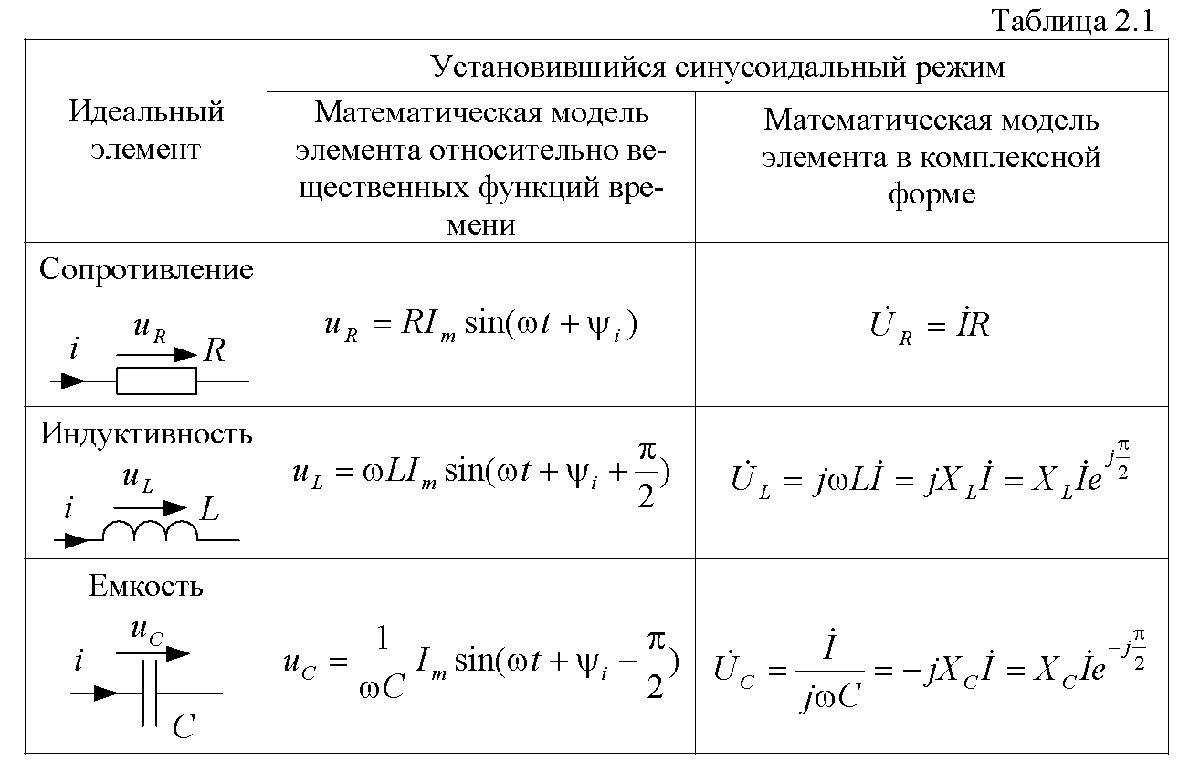 

clear
syms u_R R Ud_R u_L L u_C C I_m omega t psi_i psi_u
u_R==R*I_m*sin(omega*t+psi_i)  % Сопротивление

$$ans = u_{R}=I_{m}\,R\,\sin\left(\psi_{i}+\omega \,t\right)$$

u_L==omega*L*I_m*sin(omega*t+psi_i+pi/2)    % Индуктивность

$$ans = u_{L}=I_{m}\,L\,\omega \,\sin\left(\psi_{i}+\frac{\pi }{2}+\omega \,t\right)$$

u_C==1/(omega*C)*I_m*sin(omega*t+psi_i-pi/2)   % Емкость

$$ans = u_{C}=\frac{I_{m}\,\sin\left(\psi_{i}-\frac{\pi }{2}+\omega \,t\right)}{C\,\omega }$$

Математическая модель элемента в комплексной форме

syms Id_R Ud_L X_L Ud_C X_C Id
Ud_R==Id_R*R

$$ans = {\mathrm{Ud}}_{R}={\mathrm{Id}}_{R}\,R$$

Ud_L==1j*omega*L*Id==1j*X_L*Id==X_L*Id*exp(1j*sym(pi/2))

$$ans = \left(\left({\mathrm{Ud}}_{L}=\mathrm{Id}\,L\,\omega \,\mathrm{i}\right)=\mathrm{Id}\,X_{L}\,\mathrm{i}\right)=\mathrm{Id}\,X_{L}\,\mathrm{i}$$

Ud_C==Id/(1j*omega*C)==-1j*X_C*Id==X_C*Id*exp(-1j*sym(pi/2))

$$ans = \left(\left({\mathrm{Ud}}_{C}=-\frac{\mathrm{Id}\,\mathrm{i}}{C\,\omega }\right)=-\mathrm{Id}\,X_{C}\,\mathrm{i}\right)=-\mathrm{Id}\,X_{C}\,\mathrm{i}$$

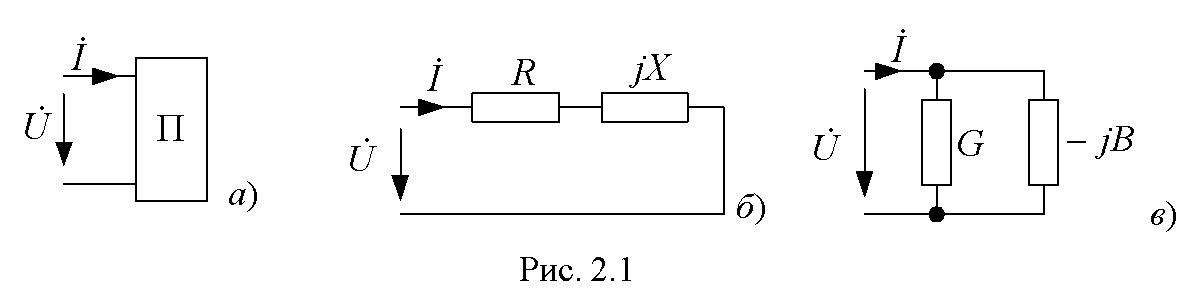

Для пассивного двухполюсника вводятся по определению следующие величины:

Комплексное сопротивление

clear
syms Zd Ud Id psi_u psi_i U I Z phi R X Yd Y G B
Zd==Ud/Id==U*exp(1j*psi_u)/(I*exp(1j*psi_i))== ...
Z*exp(1j*(psi_u-psi_i))==Z*exp(1j*phi)== ...
Z*cos(phi)+1j*Z*sin(phi)==R+1j*X

$$ans = \left(\left(\left(\left(\left(\mathrm{Zd}=\frac{\mathrm{Ud}}{\mathrm{Id}}\right)=\frac{U\,{\mathrm{e}}^{-\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\psi_{u}\,\mathrm{i}}}{\text{I}}\right)=Z\,{\mathrm{e}}^{-\psi_{i}\,\mathrm{i}+\psi_{u}\,\mathrm{i}}\right)=Z\,{\mathrm{e}}^{\varphi \,\mathrm{i}}\right)=Z\,\cos\left(\varphi \right)+Z\,\sin\left(\varphi \right)\,\mathrm{i}\right)=R+X\,\mathrm{i}$$

Комплексная проводимость

Yd==Id/Ud==(I*exp(1j*psi_i))/(U*exp(1j*psi_u))== ...
Y*exp(-1j*(psi_u-psi_i))==Y*exp(-1j*phi)== ...
Y*cos(phi)-1j*Y*sin(phi)==G-1j*B

$$ans = \left(\left(\left(\left(\left(\mathrm{Yd}=\frac{\mathrm{Id}}{\mathrm{Ud}}\right)=\frac{\text{I}\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{-\psi_{u}\,\mathrm{i}}}{U}\right)=Y\,{\mathrm{e}}^{\psi_{i}\,\mathrm{i}-\psi_{u}\,\mathrm{i}}\right)=Y\,{\mathrm{e}}^{-\varphi \,\mathrm{i}}\right)=Y\,\cos\left(\varphi \right)-Y\,\sin\left(\varphi \right)\,\mathrm{i}\right)=G-B\,\mathrm{i}$$

В таблице приведены схемы типичных участков цепи синусоидального тока и комплексные сопротивления этих участков.

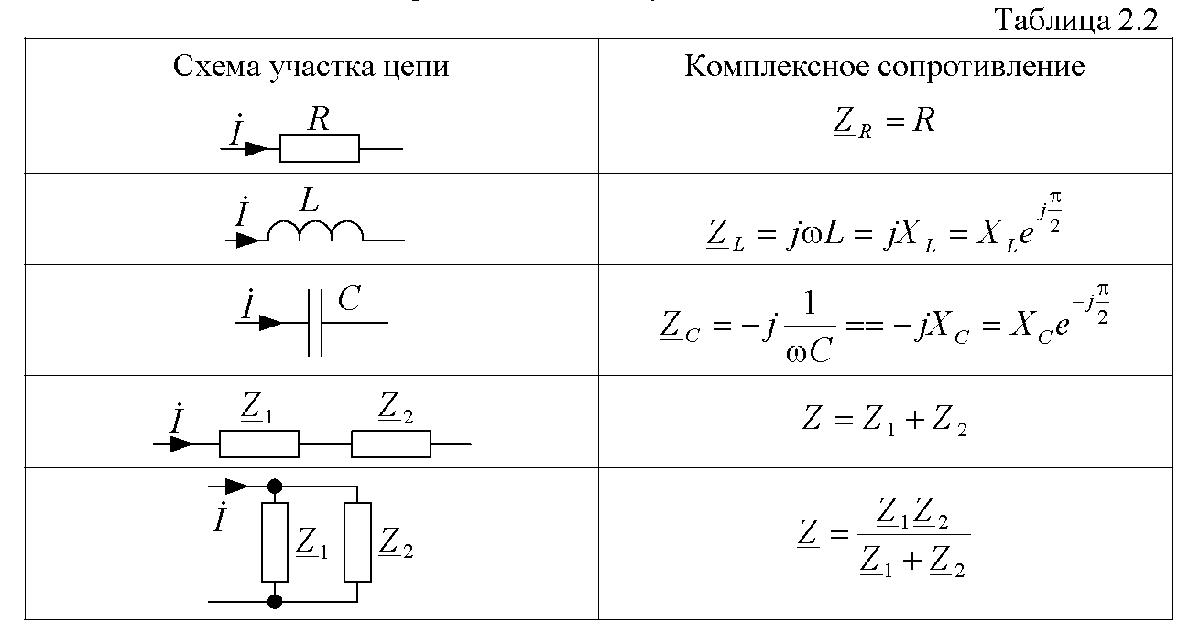 

clear
syms Zd_R Zd_L Zd_C R L C omega X_L X_C Zd1 Zd2 Zd
Zd_R==R

$$ans = {\mathrm{Zd}}_{R}=R$$

Zd_L==1j*omega*L==1j*X_L==X_L*exp(1j*sym(pi/2))

$$ans = \left(\left({\mathrm{Zd}}_{L}=L\,\omega \,\mathrm{i}\right)=X_{L}\,\mathrm{i}\right)=X_{L}\,\mathrm{i}$$

Zd_C==-1j*1/(omega*C)==-1j*X_C==X_C*exp(-1j*sym(pi/2))

$$ans = \left(\left({\mathrm{Zd}}_{C}=-\frac{\mathrm{i}}{C\,\omega }\right)=-X_{C}\,\mathrm{i}\right)=-X_{C}\,\mathrm{i}$$

Zd==Zd1+Zd2

$$ans = \mathrm{Zd}={\mathrm{Zd}}_{1}+{\mathrm{Zd}}_{2}$$

Zd==Zd1*Zd2/(Zd1+Zd2)

$$ans = \mathrm{Zd}=\frac{{\mathrm{Zd}}_{1}\,{\mathrm{Zd}}_{2}}{{\mathrm{Zd}}_{1}+{\mathrm{Zd}}_{2}}$$

Переход к комплексным сопротивлениям и проводимостям и комплексным действующим значениям напряжений и токов позволяет:

1. Записать закон Ома для участка цепи

clear
syms Ud Zd Id
Ud==Zd*Id

$$ans = \mathrm{Ud}=\mathrm{Id}\,\mathrm{Zd}$$

2. Первый закон Кирхгофа для любого узла

syms Id(k)
symsum(Id(k))==0

$$ans = \sum_{k}\mathrm{Id}\left(k\right)=0$$

3. Второй закон Кирхгофа для любого контура

syms U(l) E(l)
symsum(U(l))==symsum(E(l))

$$ans = \sum_{l}U\left(l\right)=\sum_{l}\text{E}\left(l\right)$$

Мощности источников и пассивных участков цепи в комплексной форме записи имеют вид

clear
syms Sd Ud Id U I psi_u psi_i S phi P Q
Sd==Ud*Id==U*exp(1j*psi_u)*I*exp(-1j*psi_i)==S*exp(1j*phi)== ...
S*cos(phi)+1j*S*sin(phi)==P+1j*Q

$$ans = \left(\left(\left(\left(\mathrm{Sd}=\mathrm{Id}\,\mathrm{Ud}\right)=\text{I}\,U\,{\mathrm{e}}^{-\psi_{i}\,\mathrm{i}}\,{\mathrm{e}}^{\psi_{u}\,\mathrm{i}}\right)=S\,{\mathrm{e}}^{\varphi \,\mathrm{i}}\right)=S\,\cos\left(\varphi \right)+S\,\sin\left(\varphi \right)\,\mathrm{i}\right)=P+Q\,\mathrm{i}$$

В цепи синусоидального тока выполняется баланс комплексных, активных и реактивных мощностей источников и нагрузок

syms S_EJ(l) S_Z(l) P_EJ(l) P_Z(l) Q_EJ(l) Q_Z(l)
symsum(S_EJ)==symsum(S_Z)

$$ans(l) = \sum_{l}S_{\mathrm{EJ}}\left(l\right)=\sum_{l}S_{Z}\left(l\right)$$

symsum(P_EJ)==symsum(P_Z)

$$ans(l) = \sum_{l}P_{\mathrm{EJ}}\left(l\right)=\sum_{l}P_{Z}\left(l\right)$$

symsum(Q_EJ)==symsum(Q_Z)

$$ans(l) = \sum_{l}Q_{\mathrm{EJ}}\left(l\right)=\sum_{l}Q_{Z}\left(l\right)$$

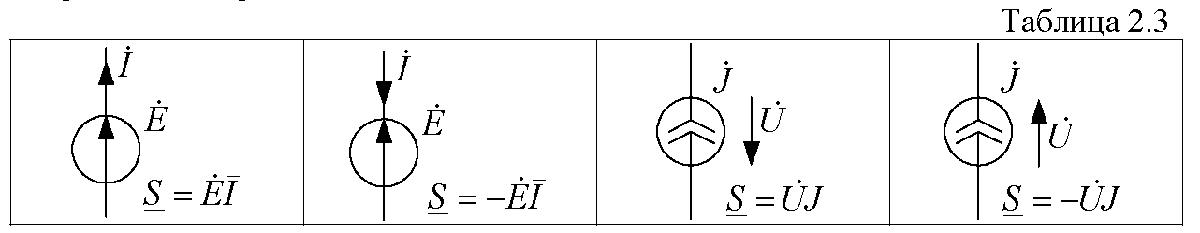

Комплексную мощность нагрузки Z удобно вычислять по выражению

syms Ud_Z Id Sd_Z Zd Z R X
Sd_Z==Ud_Z*Id==Zd*Id*Id'==Zd*I^2==I^2*R+1j*I^2*X

$$ans = \left(\left(\left({\mathrm{Sd}}_{Z}=\mathrm{Id}\,{\mathrm{Ud}}_{Z}\right)=\mathrm{Id}\,\mathrm{Zd}\,\bar{\mathrm{Id}}\right)={\text{I}}^{2}\,\mathrm{Zd}\right)={\text{I}}^{2}\,R+{\text{I}}^{2}\,X\,\mathrm{i}$$